First, read the file created by `State_parameters.m`.

dataset_date='6-19';
infile=['state_parameters_case_counts_' dataset_date '.xlsx'];
[P,txt,~]=xlsread(infile); 

Idenfify the columns that show optimal parameters values and plot associated histograms.

bet_o=P(:,3); gam_o=P(:,6); R0_o=P(:,9); k_states=isnan(R0_o);
bet_o(k_states)=[]; gam_o(k_states)=[]; R0_o(k_states)=[];
mb=mean(bet_o); mg=mean(gam_o); mr=mean(R0_o);
sb=std(bet_o); sg=std(gam_o); sr=std(R0_o);
% Marginal distributions
gd=@(x,mu,sig) exp(-((x-mu)/sig).^2)/sig/sqrt(2*pi);
% Joint distribution
C=cov(bet_o,gam_o); Q=inv(C);
gd2=@(x,y) exp(-[x-mb y-mg]*Q*[x-mb;y-mg]/2)/2/pi/sqrt(det(C));
figure(); 
x=0:0.01:1.5; y=0:0.01:0.8; [X,Y]=meshgrid(x,y); GD=zeros(size(X));
for i=1:size(X,2)
    for j=1:size(X,1)
        GD(j,i)=gd2(X(j,i),Y(j,i));
    end
end
% Linear regression between beta and gamma
disp(['R0 = ' num2str(sum(bet_o.*gam_o)./sum(gam_o.^2))])

R0 = 1.685


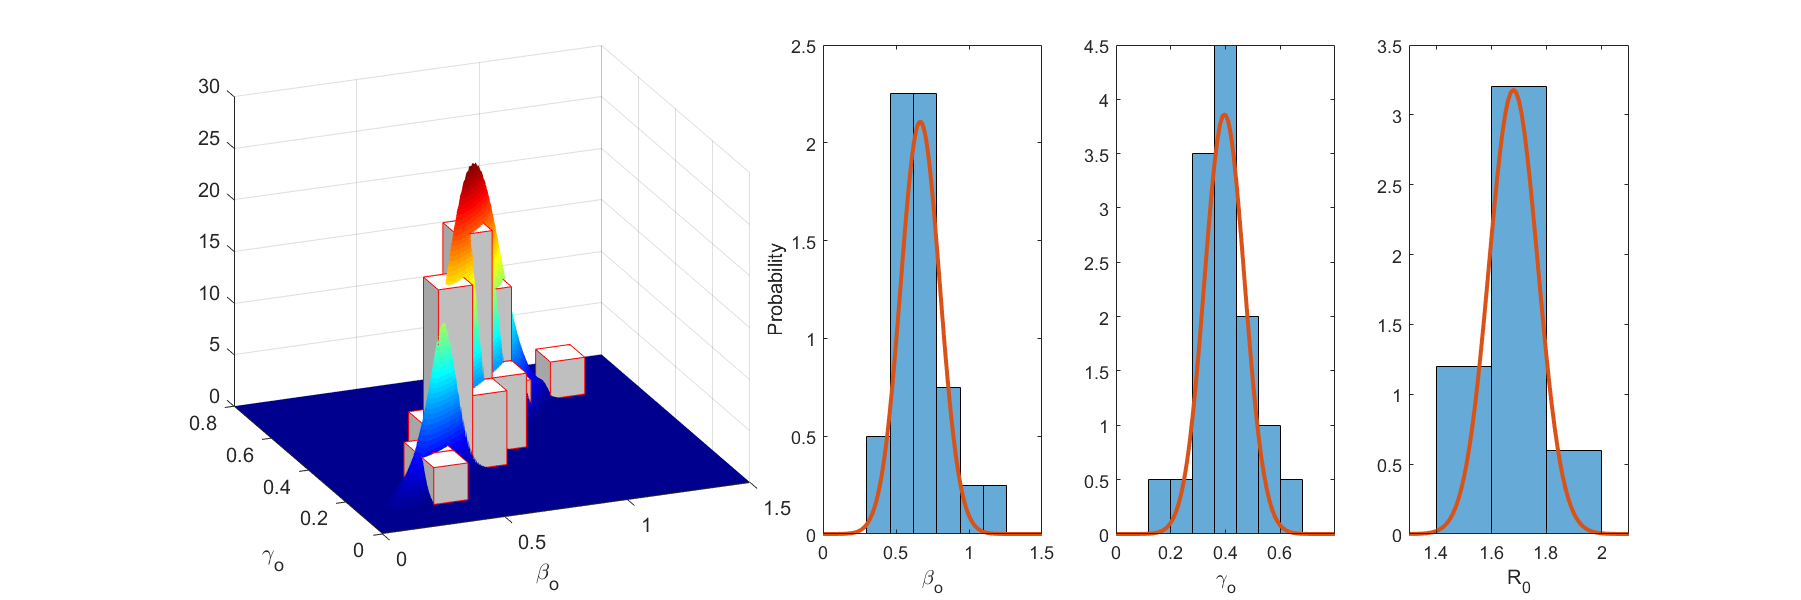

% Plots
figure(); set(gcf,'Position',[0 0 1200 400]);
subplot(1,5,[1 2]); surf(X,Y,GD), shading interp; xlabel('\beta_o');
ylabel('\gamma_o'); hold on; colormap('jet'); view([-22 24])
histogram2(bet_o,gam_o,[7 7],'Normalization','pdf','FaceColor','white',...
    'EdgeColor','red'); hold off; xlim([0 1.5]); ylim([0 0.8])
subplot(1,5,3); histogram(bet_o,6,'Normalization','pdf'); hold on;
x=0:0.01:1.5; plot(x,gd(x,mb,sb),'LineWidth',2); hold off;
xlabel('\beta_o'); ylabel('Probability'); xlim([0 1.5])
subplot(1,5,4); histogram(gam_o,7,'Normalization','pdf'); xlabel('\gamma_o');
hold on; x=0:0.01:0.8; plot(x,gd(x,mg,sg),'LineWidth',2); hold off; xlim([0 0.8])
subplot(1,5,5); histogram(R0_o,3,'Normalization','pdf'); xlabel('R_0');
hold on; x=1.3:0.01:2.1; plot(x,gd(x,mr,sr),'LineWidth',2); hold off;
xlim([1.3 2.1]); ylim([0 3.5])

% Range of optimal values
% b_min=min(P(~k_states,1)); b_max=max(P(~k_states,2));
b_min=min(bet_o); b_max=max(bet_o);
disp(['Range for beta_o: ' num2str(b_max-b_min)])

Range for beta_o: 0.93499


disp(['Standard deviation of beta_o: ' num2str(sb)])

Standard deviation of beta_o: 0.18915
